Santeri Saariokari 253345

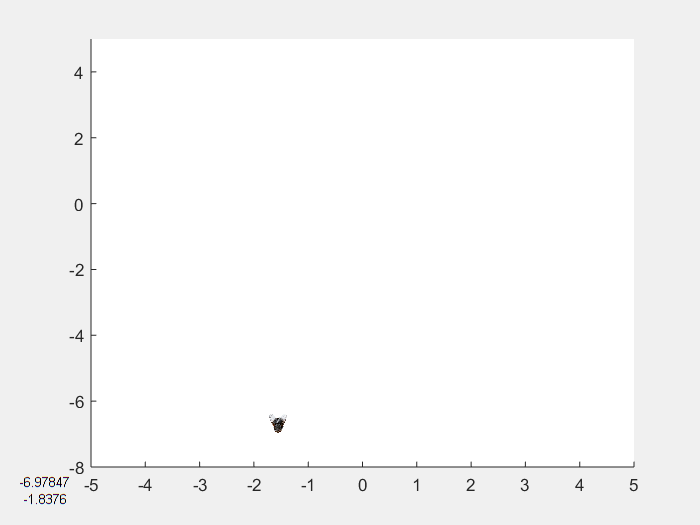

fh = figure('visible','on');

xo = 0; yo = 0;
alpha = 0.1;
axis([-5 5 -5 5]);

% h = animatedline(xo, yo, 'LineStyle', '-', 'Marker', 'none',...
%         'MarkerSize', 5, 'MaximumNumPoints', Inf, 'Color', [1 0 0]);
    
hx = uicontrol ('Style', 'text', 'Units', 'char' ,...
'Position', [1 1 11 1]);

hy = uicontrol ('Style', 'text', 'Units', 'char' ,...
'Position', [1 2 11 1]);

hold on;

marker0 = imread('karpanen0.png');
marker1 = imread('karpanen1.png');
marker2 = imread('karpanen2.png');
marker3 = imread('karpanen3.png');

latest = image([xo xo+10],[yo yo+10],marker0);

fh.UserData = true;
fh.WindowButtonDownFcn = @(hObject, event) set(hObject, 'UserData', false);

ah=gca;

while fh.UserData
    theta = rand*2*pi;

    if -pi/4 < theta && theta < pi/4
            latest.CData = marker3;
    else if pi/4 < theta && theta < (pi/4+pi/2)
            latest.CData = marker0;
    else if (pi/4+pi/2) < theta && (pi/4+2*pi/2) < theta
            latest.CData = marker2;
    else 
            latest.CData = marker1;
    end
    end
    end

    for i = 1:3
%         addpoints(h, x, y);
        x = xo + alpha*cos(theta);
        y = yo + alpha*sin(theta);
        hx.String = x;
        hy.String = y;
        
        drawnow;
        xo = x; yo = y;
        hx.String = x;
        hy.String = y;
        
        if x < ah.XLim(1) 
        ah.XLim(1) = ah.XLim(1)-3;
        elseif x > ah.XLim(2) 
            ah.XLim(2) = ah.XLim(2)+3;
        end
        if y < ah.YLim(1) 
            ah.YLim(1) = ah.YLim(1)-3;
        elseif y > ah.YLim(2) 
            ah.YLim(2) = ah.YLim(2)+3;
        end
        
            
        latest.XData = [x x+.6];
        latest.YData = [y y+.6];
    end
end